clear all
close all
clc
load ide_modelli_scara.mat

G2 = modello_continuo_q2;
figure
bode(G2)
grid on
title('Bode Identificazione Giunto 2')

tramite la funzione damp vediamo dove si trovano i poli e gli zeri del sistema identificato per trovare le frequenze di risonnza e antirisoanza per togliere il picco introdotto dalla risonanza

dataG2=damp(G2)

dataG2 =    73.6222
  712.8826
  712.8826
  986.8044
  986.8044


Di seguito viene progettato il filtro notch elimina banda con una frequenza  pari a 986.8 rad/s. 

Poi per tentativi, sono stati decisi i valori ottimali di xci_z e xci_p che indicano la selettività del filtro notch

wn = 986.8;
xci_z=0.2; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.7;
s=tf('s');
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);
figure
bode(notch)
grid on
title('Filtro Notch')

Verifica del filtro mediante l'utilizzo dei diagrammi di bode

P = G2*notch;
figure
bode(G2)
hold on
bode(notch)
grid on
bode(P)
hold off
legend('G(s)','Fn(s)','L(s)')

Prima di procedere con la taratura si inserisce un filtro bassa 

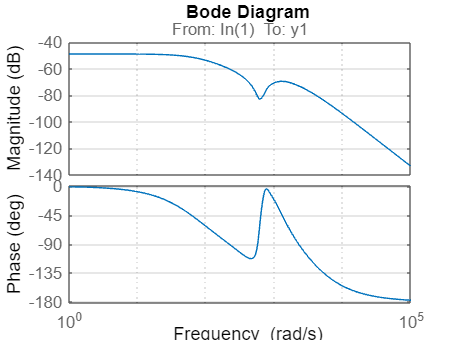

F = 1/((1/3000)*s+1);
P = P*F;
figure
bode(P)
grid on


wc = 300;
Kp=1/abs(freqresp(P,wc))

Kp = 1.5739e+03

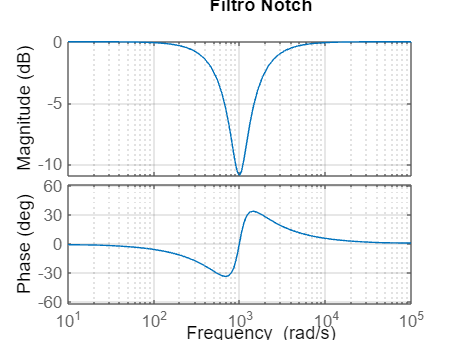



C = Kp;
L_Int = C*P;
figure
title('Kp*Fn*G2')
margin(L_Int)
grid on

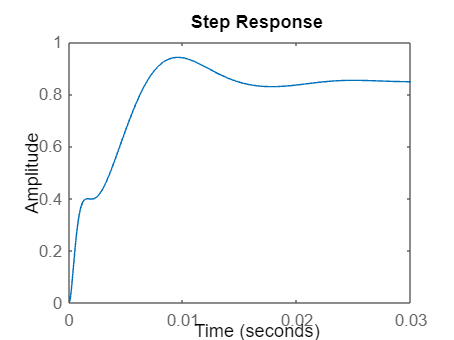


LoopInt = feedback(L_Int,1);
figure
step(LoopInt)

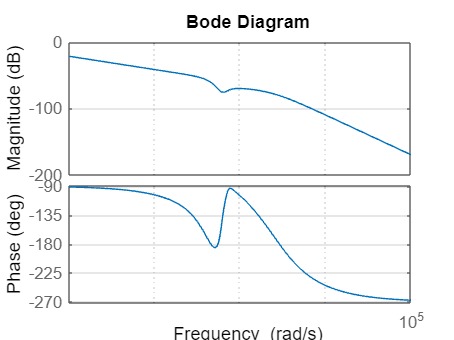

G1 = LoopInt*1/s;
bode(G1)
grid on

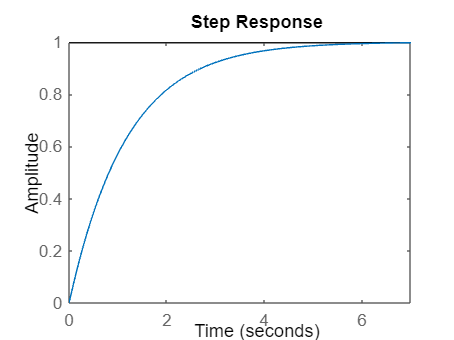

% tf(G1)
figure
step(feedback(G1,1))


wc_des=200;
J=@(x)pivel_cost_function(x,G1,wc_des);
MS=1.4;
wh=2000;
Fh_max=0.1;
wl=0.1;
Dh_max=0.1;%disturbo sul carico ridotto di almeno 10 volte
 
w_vector=logspace(-3,3)'; % [10^-3,10^3]
w_vector=sort([w_vector;wl;wh]);

nlcon=@(x)pivel_constraints(x,G1,w_vector,MS,wh,Fh_max,wl,Dh_max);%anonious function

Risolvo il problema con fmincon, la soluzione è locale.

Impongo che $K_p\in[0.01,10000]$ e $K_i\in[0.01,10000]$

x0=[1,0.1];% scegliere un punto di partenza meglio provarne di diversi
x=fmincon(J,x0,[],[],[],[],[0.001 0.000001],[10000 10000],nlcon);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =   162.0181    0.0002


Kp=x(1)

Kp = 162.0181

Ki=x(2)

Ki = 1.9534e-04

C1=tf([Kp Ki],[1 0]);

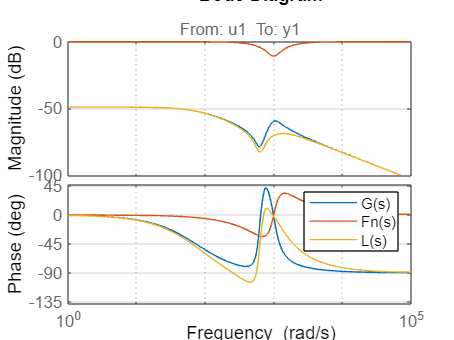

figure
bode(C1*G1)

grid on
allmargin(C1*G1)

ans = struct with fields:
     GainMargin: [0 6.6022 20.4507 65.5580]
    GMFrequency: [0 455.4716 554.1561 2.8847e+03]
    PhaseMargin: 70.9195
    PMFrequency: 137.6455
    DelayMargin: 0.0090
    DMFrequency: 137.6455
         Stable: 1


C_fr=freqresp(C1*G1,w_vector);
S_fr=1./(1+(C_fr)); % S = 1/(1+L) sensitivity function
max(abs(S_fr))

ans = 1.4000